# Conceptos básicos de probabilidad y estadística

## Interpretaciones

Consideremos el experimento de lanzar una moneda.  Compararemos la interpretación clásica $P =N/N_A$ con la frecuentista $P = \lim_{n\to\infty}FR$, donde $FR = n/n_A$

% Flip coin experiment H->0 T->1 P=0.5
clear;
P=0.5;

% Freq
N = 4000;
h = 0;
t = 0;
ch = 1;
ct = 1;

for ii=1:N
    % Coin toss
    coin = round(rand);
    
    if coin == 0
        h=h+1;
        H(ch) = h;
        PH(ch) = H(ch)/ii;
        ch=ch+1;
    else
        t=t+1;
        T(ct) = t;
        PT(ct) = T(ct)/ii;
        ct=ct+1;
    end 
end

Vamos a visualizar la interpretación frecuentista, y la compararemos con la interpretación clásica

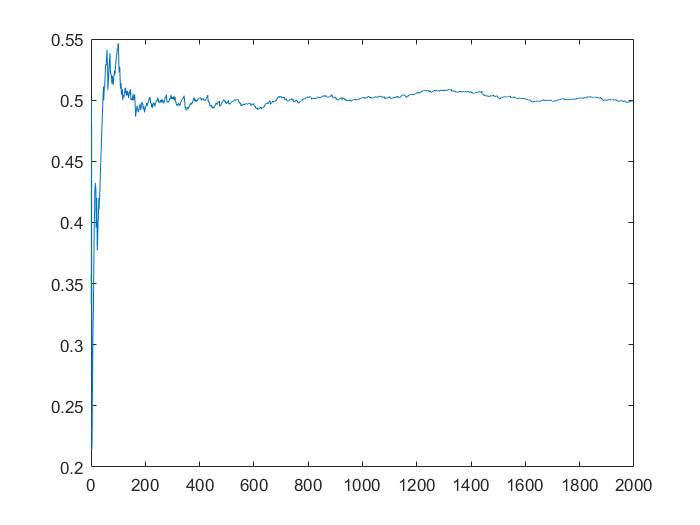

plot([1:length(PH)], PH)
hold on

### Ejercicio:

Realiza una rutina que simule el lanzado de un dado de seis lados.  Genera un gráfico similar al del ejemplo anterior.

## Distribuciones de probabilidad

### Uniforme

La función de densidad de probabilidad de una v.a. uniformemente distribuída en el intervalo $(a,b)$ es


$$f_X(x;a,b) = \frac{1}{b-a}$$
 

con $a<x<b$.  Generemos números aleatorios uniformemente distribuídos en Matlab.

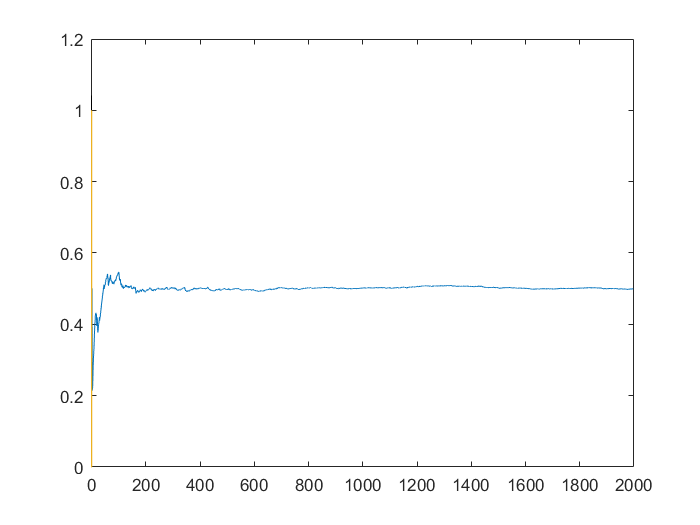

clear;

% Number of elements
N = 10000;

% Lets define the distribution and parameters
a = 0;
b = 1;
pd = makedist("Uniform",a,b);
rr = random(pd, 1, N);
nbins = 10;

% Theoretical evaluation
x = -2:0.01:2;
rrpdf = (1/(b-a)) .* (x>a) .* (x<b);

% visualization
histogram(rr,nbins,'Normalization','pdf')
hold on
plot(x,rrpdf)
hold off

### Normal

También conocida como distribución Gaussiana, aparece en muchas ramas de la ciencia.  Su pdf es

$f_X(x;\mu,\sigma^2) = \frac{1}{\sigma\sqrt{2\pi}}e^{-\frac{(x-\mu)^2}{2\sigma^2}}$, con $-\infty<x<\infty$, $-\infty<\mu<\infty$ y $\sigma^2>0$.

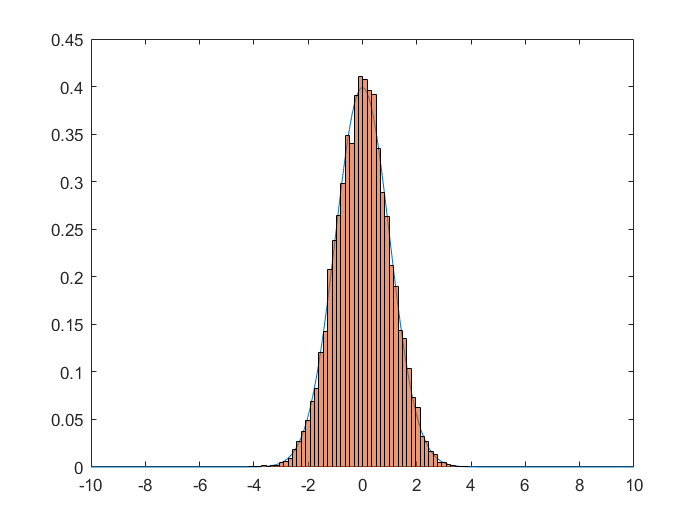

clear;

N = 10000;

% Distribution
mu = 0;
sig = 1;
pd = makedist('Normal',mu,sig);
rr = random(pd,1,N);
nbins = 50;

% Theoretical
x = -10:0.01:10;
rrpdf = (1/sig/sqrt(2*pi)) * exp(-((x-mu).^2)/2/sig^2);

% Visualization
plot(x,rrpdf);
hold on
histogram(rr,nbins,'Normalization','pdf')
hold off

### Ejercicio

Revisa la documentación de Matlab para generar números cuasi-aleatorios reproducibles.  Genera números aleatorios siguiendo las siguientes distribuciones:

- $X$~Beta$(\alpha=2, \beta=5)$

- $X$~Gamma$(k=2, \theta=2)$

### Weibull

clear;

% Number of elemens
N = 1;

% Distribution
lam = 1;
k = 1.5;

We will use the "rng" function to have some control over the random number generator

rng('default');
s1 = rng;
rng(1,'twister');
s2 = rng;
rng('shuffle');
s3 = rng;

rng(0,'twister');

pd = makedist('Weibull',lam,k);
random(pd,1,10)

## Transformaciones

Usaremos el teorema visto en clase


$$f_Y(y) = f_x(g^{-1}(y))\left|\frac{d}{dy} g^{-1}(y) \right|$$


Para la transformación $Y=1/X$ donde $X$~Gamma($\alpha,\beta$).  Abordaremos la pdf de dos maneras:

clear;

% Cantidad de numeros aleatorios
N = 10000;
nbins = 50;

% Parametros de la distribucion
alf = 4;
bet = 1/10;

% Generacion de numeros aleatorios
rng('default');
pd = makedist('Gamma',alf,bet);
rgamma = random(pd, 1, N);
rinv = 1./rgamma;

% Expresion teorica
y = 0:0.001:40;
rpdf = (1/(gamma(alf) * bet^alf)) * ...
    (1./y).^(alf+1) .* exp(-1./(bet*y)); 

%Visualizacion
histogram(rinv, nbins, 'Normalization','pdf')
hold on 
plot(y,rpdf)
hold off

## Valor esperado

Recordemos la definición del valor esperado

$E(X) = \int x\: f_X(x) \:dx$,

además conocemos la Ley del estadista inconsciente


$$E(g(X)) = \int g(x)\: f_X(x)\: dx$$


Con esto calcularemos el valor esperado de la v.a. $Y=-\log(X)$, con $X$~Uniforme$(0,1)$.

clear;

N = 10000;

% Parametros de la distribucion
aa = 0;
bb = 1;

% Numeros aleatorios U(0,1)
rng('default');
pd = makedist('Uniform',aa,bb);
xx = random(pd,1,N);

% Aqui hacemos la transformacion
yy = -log(xx);
meanY = mean(yy)

% Numeros aleatorios Exp(1)
rng('default')
pd2 = makedist('Exponential',1);
yy2 = random(pd2, 1, N);

meanY2 = mean(yy2)

Notemos que en este ejercicio resolvimos


$$-\int_0^1 \log(x)\:dx$$
